# Example 17.5

Consider the sawtooth periodic waveform with fundamental period $T_0$ shown in [Fig. 77](https://cpjobling.github.io/eg-150-textbook/fourier_series/2/exp_fs1.html#fig-ex-17-5).

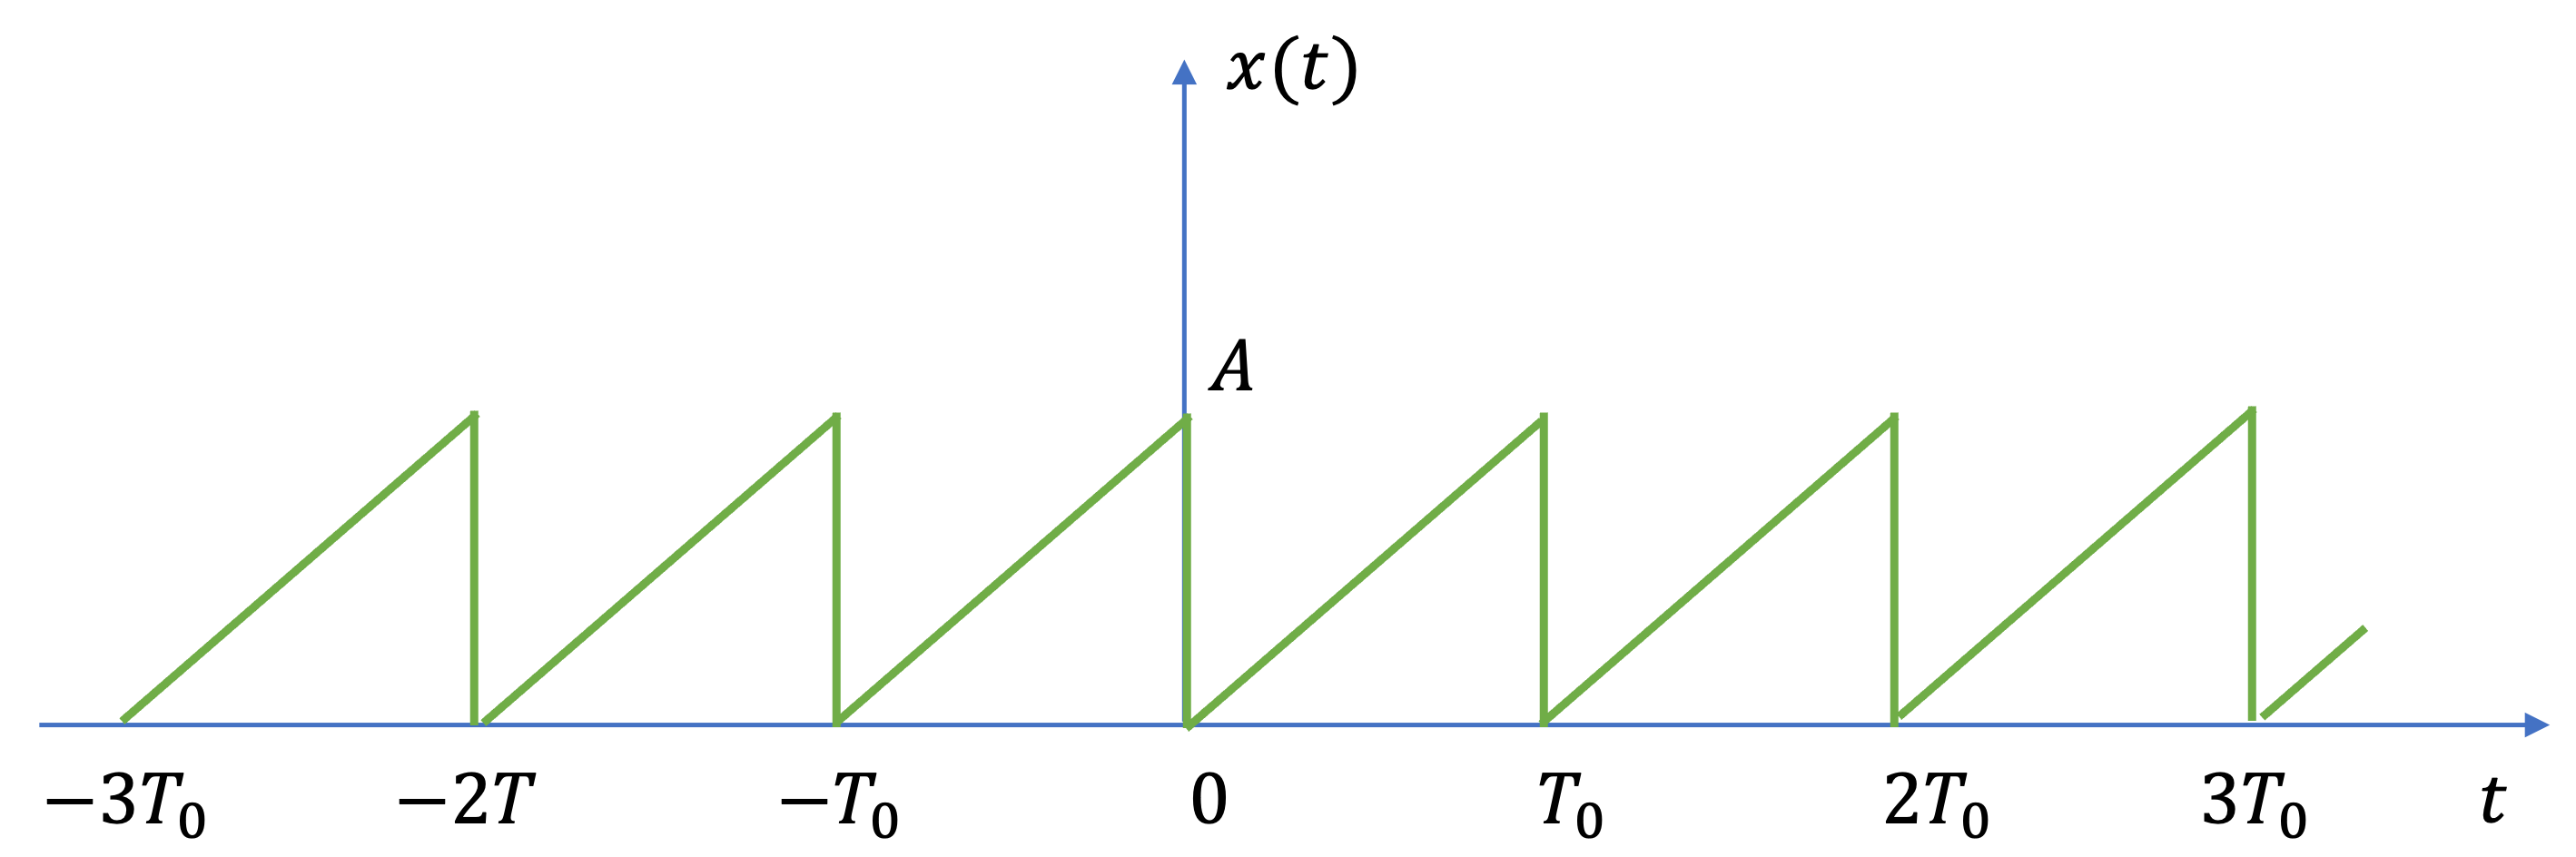

*Fig. 77 *Periodic Waveform for Example 17.5

a) Compute the Fourier series coefficients $C_k$ for this signal.

sympref('AbbreviateOutput',false)

ans = logical
   0


syms A theta k Omega_0 T_0 t
assume(k,'integer')
assume(A,'real')
assume(T_0>0)
assume(Omega_0>0)
f(t) = (A/T_0)*t;
C_0 = (A/T_0)*(int(f(t),t,0,T_0))

$$C\_0 = \frac{A^{2}}{2}$$

C_k = (A/T_0)*int(f(t)*exp(-j*k*Omega_0*t),t,0,T_0)

$$C\_k = -\frac{A^{2}\,\left(\frac{1}{{\Omega_{0}}^{2}\,k^{2}}-\frac{{\mathrm{e}}^{-\Omega_{0}\,T_{0}\,k\,\mathrm{i}}\,\left(1+\Omega_{0}\,T_{0}\,k\,\mathrm{i}\right)}{{\Omega_{0}}^{2}\,k^{2}}\right)}{{T_{0}}^{2}}$$


C_k = subs(C_k,Omega_0,sym(2*pi)/T_0)

$$C\_k = -\frac{A^{2}\,\left(\frac{{T_{0}}^{2}}{4\,k^{2}\,\pi^{2}}-\frac{{T_{0}}^{2}\,{\mathrm{e}}^{-2\,\pi \,k\,\mathrm{i}}\,\left(1+2\,\pi \,k\,\mathrm{i}\right)}{4\,k^{2}\,\pi^{2}}\right)}{{T_{0}}^{2}}$$

C_k = simplify(C_k)

$$C\_k = \frac{A^{2}\,\mathrm{i}}{2\,k\,\pi }$$

K = [1:11];
C_k = subs(C_k,k,K)

$$C\_k = \left(\begin{array}{ccccccccccc} \frac{A^{2}\,\mathrm{i}}{2\,\pi } & \frac{A^{2}\,\mathrm{i}}{4\,\pi } & \frac{A^{2}\,\mathrm{i}}{6\,\pi } & \frac{A^{2}\,\mathrm{i}}{8\,\pi } & \frac{A^{2}\,\mathrm{i}}{10\,\pi } & \frac{A^{2}\,\mathrm{i}}{12\,\pi } & \frac{A^{2}\,\mathrm{i}}{14\,\pi } & \frac{A^{2}\,\mathrm{i}}{16\,\pi } & \frac{A^{2}\,\mathrm{i}}{18\,\pi } & \frac{A^{2}\,\mathrm{i}}{20\,\pi } & \frac{A^{2}\,\mathrm{i}}{22\,\pi } \end{array}\right)$$

C_minus_k = conj(flip(C_k))

$$C\_minus\_k = \left(\begin{array}{ccccccccccc} -\frac{A^{2}\,\mathrm{i}}{22\,\pi } & -\frac{A^{2}\,\mathrm{i}}{20\,\pi } & -\frac{A^{2}\,\mathrm{i}}{18\,\pi } & -\frac{A^{2}\,\mathrm{i}}{16\,\pi } & -\frac{A^{2}\,\mathrm{i}}{14\,\pi } & -\frac{A^{2}\,\mathrm{i}}{12\,\pi } & -\frac{A^{2}\,\mathrm{i}}{10\,\pi } & -\frac{A^{2}\,\mathrm{i}}{8\,\pi } & -\frac{A^{2}\,\mathrm{i}}{6\,\pi } & -\frac{A^{2}\,\mathrm{i}}{4\,\pi } & -\frac{A^{2}\,\mathrm{i}}{2\,\pi } \end{array}\right)$$


C_k_array = [C_minus_k,C_0,C_k]

$$C\_k\_array = \left(\begin{array}{ccccccccccccccccccccccc} -\frac{A^{2}\,\mathrm{i}}{22\,\pi } & -\frac{A^{2}\,\mathrm{i}}{20\,\pi } & -\frac{A^{2}\,\mathrm{i}}{18\,\pi } & -\frac{A^{2}\,\mathrm{i}}{16\,\pi } & -\frac{A^{2}\,\mathrm{i}}{14\,\pi } & -\frac{A^{2}\,\mathrm{i}}{12\,\pi } & -\frac{A^{2}\,\mathrm{i}}{10\,\pi } & -\frac{A^{2}\,\mathrm{i}}{8\,\pi } & -\frac{A^{2}\,\mathrm{i}}{6\,\pi } & -\frac{A^{2}\,\mathrm{i}}{4\,\pi } & -\frac{A^{2}\,\mathrm{i}}{2\,\pi } & \frac{A^{2}}{2} & \frac{A^{2}\,\mathrm{i}}{2\,\pi } & \frac{A^{2}\,\mathrm{i}}{4\,\pi } & \frac{A^{2}\,\mathrm{i}}{6\,\pi } & \frac{A^{2}\,\mathrm{i}}{8\,\pi } & \frac{A^{2}\,\mathrm{i}}{10\,\pi } & \frac{A^{2}\,\mathrm{i}}{12\,\pi } & \frac{A^{2}\,\mathrm{i}}{14\,\pi } & \frac{A^{2}\,\mathrm{i}}{16\,\pi } & \frac{A^{2}\,\mathrm{i}}{18\,\pi } & \frac{A^{2}\,\mathrm{i}}{20\,\pi } & \frac{A^{2}\,\mathrm{i}}{22\,\pi } \end{array}\right)$$

Calculate and plot spectrum

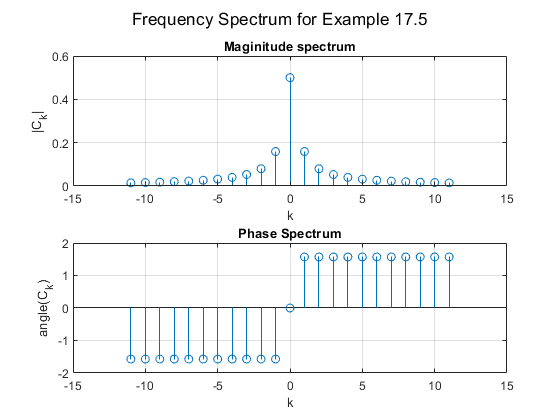

spectrum = subs(C_k_array,[A,T_0],[1,1]);
mag = double(abs(spectrum));
phase = double(angle(spectrum));
subplot(211)
stem(-11:11,mag),...
    grid,title('Maginitude spectrum'),xlabel('k'),ylabel('|C_k|')
subplot(212)
stem(-11:11,phase),...
    grid,title('Phase Spectrum'),xlabel('k'),ylabel('angle(C_k)')
sgtitle('Frequency Spectrum for Example 17.5')

b) Give an expression for the trig. Fourier series for this signal.

a_k = C_k + conj(C_k)

$$a\_k = \left(\begin{array}{ccccccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

b_k = j*(C_k - conj(C_k))

$$b\_k = \left(\begin{array}{ccccccccccc} -\frac{A^{2}}{\pi } & -\frac{A^{2}}{2\,\pi } & -\frac{A^{2}}{3\,\pi } & -\frac{A^{2}}{4\,\pi } & -\frac{A^{2}}{5\,\pi } & -\frac{A^{2}}{6\,\pi } & -\frac{A^{2}}{7\,\pi } & -\frac{A^{2}}{8\,\pi } & -\frac{A^{2}}{9\,\pi } & -\frac{A^{2}}{10\,\pi } & -\frac{A^{2}}{11\,\pi } \end{array}\right)$$

a_0 = 2*C_0

$$a\_0 = A^{2}$$

ft = a_0/2;
for n = 1:11
    ft = ft + a_k(n)*cos(n*Omega_0*t) + b_k(n)*sin(n*Omega_0*t);
end
ft

$$ft = \frac{A^{2}}{2}-\frac{A^{2}\,\sin\left(\Omega_{0}\,t\right)}{\pi }-\frac{A^{2}\,\sin\left(2\,\Omega_{0}\,t\right)}{2\,\pi }-\frac{A^{2}\,\sin\left(3\,\Omega_{0}\,t\right)}{3\,\pi }-\frac{A^{2}\,\sin\left(4\,\Omega_{0}\,t\right)}{4\,\pi }-\frac{A^{2}\,\sin\left(5\,\Omega_{0}\,t\right)}{5\,\pi }-\frac{A^{2}\,\sin\left(6\,\Omega_{0}\,t\right)}{6\,\pi }-\frac{A^{2}\,\sin\left(7\,\Omega_{0}\,t\right)}{7\,\pi }-\frac{A^{2}\,\sin\left(8\,\Omega_{0}\,t\right)}{8\,\pi }-\frac{A^{2}\,\sin\left(9\,\Omega_{0}\,t\right)}{9\,\pi }-\frac{A^{2}\,\sin\left(10\,\Omega_{0}\,t\right)}{10\,\pi }-\frac{A^{2}\,\sin\left(11\,\Omega_{0}\,t\right)}{11\,\pi }$$

figure
Ft = subs(ft,[A,T_0],[1,1])

$$Ft = \frac{1}{2}-\frac{\sin\left(2\,\Omega_{0}\,t\right)}{2\,\pi }-\frac{\sin\left(3\,\Omega_{0}\,t\right)}{3\,\pi }-\frac{\sin\left(4\,\Omega_{0}\,t\right)}{4\,\pi }-\frac{\sin\left(5\,\Omega_{0}\,t\right)}{5\,\pi }-\frac{\sin\left(6\,\Omega_{0}\,t\right)}{6\,\pi }-\frac{\sin\left(7\,\Omega_{0}\,t\right)}{7\,\pi }-\frac{\sin\left(8\,\Omega_{0}\,t\right)}{8\,\pi }-\frac{\sin\left(9\,\Omega_{0}\,t\right)}{9\,\pi }-\frac{\sin\left(10\,\Omega_{0}\,t\right)}{10\,\pi }-\frac{\sin\left(11\,\Omega_{0}\,t\right)}{11\,\pi }-\frac{\sin\left(\Omega_{0}\,t\right)}{\pi }$$

Ft = vpa(Ft,3)

$$Ft = 0.5-0.318\,\sin\left(\Omega_{0}\,t\right)-0.159\,\sin\left(2.0\,\Omega_{0}\,t\right)-0.0796\,\sin\left(4.0\,\Omega_{0}\,t\right)-0.0398\,\sin\left(8.0\,\Omega_{0}\,t\right)-0.0354\,\sin\left(9.0\,\Omega_{0}\,t\right)-0.0637\,\sin\left(5.0\,\Omega_{0}\,t\right)-0.0318\,\sin\left(10.0\,\Omega_{0}\,t\right)-0.0289\,\sin\left(11.0\,\Omega_{0}\,t\right)-0.106\,\sin\left(3.0\,\Omega_{0}\,t\right)-0.0531\,\sin\left(6.0\,\Omega_{0}\,t\right)-0.0455\,\sin\left(7.0\,\Omega_{0}\,t\right)$$

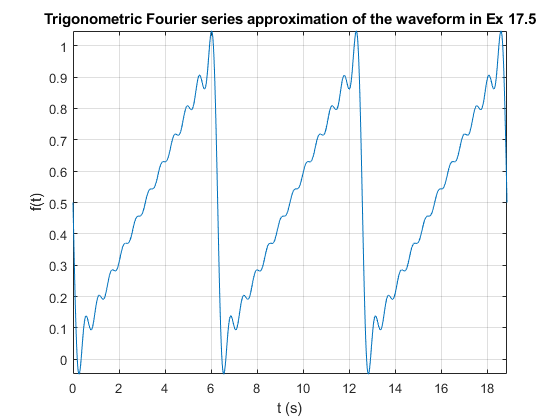

fplot(subs(Ft,Omega_0,1),[0,6*pi]),...
    grid,title('Trigonometric Fourier series approximation of the waveform in Ex 17.5'),...
    xlabel('t (s)'),ylabel('f(t)')

Simplifications

exp(-j*[1:5]*pi)

ans =   -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i   1.0000 + 0.0000i  -1.0000 - 0.0000i


C_k = (A/T_0)*int(f(t)*exp(-j*k*Omega_0*t),t,0,T_0)

$$C\_k = -\frac{A^{2}\,\left(\frac{1}{{\Omega_{0}}^{2}\,k^{2}}-\frac{{\mathrm{e}}^{-\Omega_{0}\,T_{0}\,k\,\mathrm{i}}\,\left(1+\Omega_{0}\,T_{0}\,k\,\mathrm{i}\right)}{{\Omega_{0}}^{2}\,k^{2}}\right)}{{T_{0}}^{2}}$$

C_k = simplify(subs(C_k,Omega_0,sym(2*pi)/T_0))

$$C\_k = \frac{A^{2}\,\mathrm{i}}{2\,k\,\pi }$$

a_k = C_k + conj(C_k)

$$a\_k = 0$$

b_k = j*(C_k - conj(C_k))

$$b\_k = -\frac{A^{2}}{k\,\pi }$$